# ADCS Final

Dillon Allen

## Question 1

### 1.1 For 2-1-2 Euler Transform with angles $\theta_1$, $\theta_2$, $\theta_3$, what angles, if any, are undefined?

Ans: $\theta_2 = 0, \pi$makes the second rotation an identity matrix and makes identifying the other angles impossible.

### 1.2 Spacecraft is halfway between Earth and Mars. What sources of disturbance do we need to consider?

Since we are not nearby any planets and outside of any sources of magnetic fields, our disturbance force will be SRP.

### 1.3 Use at least 2 criteria to show that [A] is not a valid DCM


$$\left[A\right] = \pmatrix{ -1 & 0 & 0 \cr 0 & \frac{\sqrt{3}}{2} & \frac{1}{2} \cr 0 & -\frac{1}{2} & \frac{\sqrt{3}}{2} }$$


We will use two criteria, det(A) = +1 and we will check to see if the only real eigenvalue is +1.

A = [-1 0 0; 0 sqrt(3)/2 1/2; 0 -1/2 sqrt(3)/2];

% check one, does detA = +/- 1?
detA = det(A);
if(detA == 1)
    fprintf("detA = +1, valid DCM")
else
    fprintf("Not a valid determinant value, %f. Not a DCM", detA);
end

Not a valid determinant value, -1.000000. Not a DCM

% Check via inspection 
evalsA = eig(A)

evalsA =    0.8660 + 0.5000i
   0.8660 - 0.5000i
  -1.0000 + 0.0000i


for i = 1:3
    if isreal(evalsA(i))
        if evalsA(i) == 1
            frpintf("valid e-val")
        else
            fprintf("not valid e-val: %f", evalsA(i))
        end
    end
end

not valid e-val: -1.000000

### Problem 1.4 State any two conditions under which this vector equation is valid

#### 
$$\dot{\omega} + \omega \times [I] \omega = 0$$


- $\omega$ = 0

- $\omega$ is constant and $I_x = I_y = I_z$

### Problem 1.5 

## Question 2

#### 
$$[I] = \pmatrix{6 & -2 & 0 \cr -2 & 6 & 0 \cr 0 & 0 & 7}$$


### Problem 2.1 What are the principal moments of inertia?

I = [6 -2 0; -2 6 0; 0 0 7]

I =      6    -2     0
    -2     6     0
     0     0     7


[V,E] = eig(I)

V =    -0.7071         0   -0.7071
   -0.7071         0    0.7071
         0    1.0000         0


E =      4     0     0
     0     7     0
     0     0     8


Ip = V' * I * V

Ip =     4.0000         0         0
         0    7.0000         0
         0         0    8.0000


% Confirming that we get the initial MOI matrix when working backwards
I_old = inv(V')*Ip*inv(V)

I_old =      6    -2     0
    -2     6     0
     0     0     7


### Problem 2.2 Is the spacecraft stable in simple spin about the Z axis?

Yes, $I_z > I_x$ and $I_z > I_y$.

### Problem 2.3 How does the answer change if the spacecraft is quasi-rigid?

The spin is still stable along the Z-axis, as $I_z > I_x$.

### Problem 2.4 Is it stable about the other two axes if the spacecraft is quasi-rigid?

No, it will nutate until it spins across its major axis.

## Problem 3

### Given a 3-2-1 Inertial to Body Euler Angles and their Rates

### 
$$\psi = 10^{\circ} \ \theta = -15^{\circ} \ \phi = 20^{\circ}$$


### 
$$\dot{\psi} = 1^{\circ}/s \ \dot{\theta} = 1^{\circ}/s \ \dot{\phi} = 0^{\circ}/s$$


### Problem 3.1 Find the Angular Velocity in the Body Frame

We will use the following equation from the notes for a 3-2-1 body rates (Final Review, Slide 22)

#### 
$$\omega = \pmatrix{\omega_x \cr \omega_y \cr \omega_z} = \pmatrix{\dot{\phi} \cr 0 \cr 0} + [A_{\theta}]\pmatrix{0 \cr \dot{\theta} \cr 0} + [A_{\theta}][A_{\psi}]\pmatrix{0 \cr 0 \cr \dot{\psi}}$$


psi       = deg2rad(10); 
theta     = deg2rad(-15); 
phi       = deg2rad(20);
psi_dot   = deg2rad(1);
theta_dot = deg2rad(1);
phi_dot   = 0;

A_psi = [cos(psi) sin(psi) 0; -sin(psi) cos(psi) 0; 0 0 1];
A_theta = [cos(theta) 0 -sin(theta); 0 1 0; -sin(theta) 0 cos(theta)];
A_phi = [1 0 0; 0 cos(phi) sin(phi); 0 -sin(phi) cos(phi)];

omega_br = [phi_dot; 0; 0] + A_theta * [0; theta_dot; 0] + ...
            A_theta * A_psi * [0; 0; psi_dot];
fprintf("body rates are {%f, %f, %f} (rad/s)", ...
        omega_br(1), omega_br(2), omega_br(3));

body rates are {0.004517, 0.017453, 0.016859} (rad/s)

### Problem 3.2 Find the DCM from Body to Inertial Frame

DCM_bi = A_phi * A_theta * A_psi

DCM_bi =     0.9513    0.1677    0.2588
   -0.0760    0.9408    0.3304
    0.2989   -0.2946    0.9077


### Problem 3.3 Find the Angular Velocity in the Inertial Frame

omega_i = DCM_bi * omega_br;
fprintf("Inertial Angular Velocities: {%f, %f, %f} (rad/s)", ...
        omega_i(1), omega_i(2), omega_i(3));

Inertial Angular Velocities: {0.011588, 0.021646, 0.011511} (rad/s)

## Problem 4

### Problem 4.1 Derive the 1-2-3 DCM for angles $\phi$, $\theta$, $\psi$ respectively. 

#### 
$$A_{123} = A_{\phi \theta \psi} = A_{\psi} A_{\theta} A_{\phi}$$


#### 
$$A_\phi = \pmatrix{ 1 & 0 & 0 \cr 0 & cos(\phi) & sin(\phi) \cr 0 & -sin(\phi) & cos(\phi)}$$


#### 
$$A_\theta = \pmatrix{cos(\theta) & 0 & -sin(\theta) \cr 0 & 1 & 0 \cr sin(\theta) & 0 & cos(\theta)}$$


#### 
$$A_\psi = \pmatrix{cos(\psi) & sin(\psi) & 0 \cr -sin(\psi) & cos(\psi) & 0 \cr 0 & 0 & 1}$$


#### 
$$A_{\phi \theta \psi} = \pmatrix{cos(\psi) & sin(\psi) & 0 \cr -sin(\psi) & cos(\psi) & 0 \cr 0 & 0 & 1} \pmatrix{cos(\theta) & 0 & -sin(\theta) \cr 0 & 1 & 0 \cr sin(\theta) & 0 & cos(\theta)} \pmatrix{ 1 & 0 & 0 \cr 0 & cos(\phi) & sin(\phi) \cr 0 & -sin(\phi) & cos(\phi)}$$


#### 
$$A_{\phi \theta \psi} = \pmatrix{cos(\psi) & sin(\psi) & 0 \cr -sin(\psi) & cos(\psi) & 0 \cr 0 & 0 & 1} \pmatrix{ cos(\theta) & sin(\theta) sin(\phi) & -cos(\phi) sin(\theta) \cr 0 & cos(\phi) & sin(\phi) \cr sin(\theta) & -cos(\theta) sin(\phi) & cos(\theta) cos(\phi)}$$


$A_{\phi \theta \psi} = \pmatrix{ cos(\theta) cos(\psi) & cos(\psi) sin(\theta) sin(\phi) + cos(\phi) sin(\psi) & -cos(\phi)cos(\psi)sin(\theta) + sin(\phi) sin(\psi) \cr -cos(\theta) sin(\psi) & cos(\phi) cos(\psi) - sin(\theta) sin(\phi) sin(\psi) & cos(\psi) sin(\phi) + cos(\phi) sin(\theta) sin(\psi) \cr sin(\theta) & -cos(\theta) sin(\phi) & cos(\theta) cos(\phi)}$

### Problem 4.2 Show that gimbal lock occurs at $\theta = \frac{3 \pi}{2}$

#### 
$$A_{\phi, \frac{3 \pi}{2}, \psi} = \pmatrix{ 0 & -cos(\psi) sin(\phi) + cos(\phi) sin(\psi) & cos(\phi)cos(\psi) + sin(\phi) sin(\psi) \cr 0 & cos(\phi) cos(\psi) + sin(\phi) sin(\psi) & cos(\psi) sin(\phi) - cos(\phi) sin(\psi) \cr -1 & 0 & 0}$$


From here, we are unable to isolate any of the euler angles, so they have become undefined. 

## Problem 5

### Problem 5.1 Obtain the I2B DCM via the TRIAD Algorithm

ui = [0.8273 0.5541 -0.0920]

ui =     0.8273    0.5541   -0.0920


vi = [-0.8285 0.5522 -0.0955]

vi =    -0.8285    0.5522   -0.0955



ui_bar = ui / norm(ui)

ui_bar =     0.8273    0.5541   -0.0920


vi_bar = cross(ui_bar, vi) / norm(cross(ui_bar, vi))

vi_bar =    -0.0023    0.1671    0.9859


wi_bar = cross(ui_bar, vi_bar) / norm(cross(ui_bar, vi_bar))

wi_bar =     0.5617   -0.8155    0.1395



ub = [-0.1517 -0.9669 0.2050]

ub =    -0.1517   -0.9669    0.2050


vb = [-0.8393 0.4494 -0.3044]

vb =    -0.8393    0.4494   -0.3044



ub_bar = ub / norm(ub)

ub_bar =    -0.1517   -0.9669    0.2050


vb_bar = cross(ub_bar, vb) / norm(cross(ub_bar, vb))

vb_bar =     0.2177   -0.2350   -0.9473


wb_bar = cross(ub_bar, vb_bar) / norm(cross(ub_bar, vb_bar))

wb_bar =     0.9641   -0.0991    0.2462



A_i2b = [ub_bar.' vb_bar.' wb_bar.']*[ui_bar.' vi_bar.' wi_bar.']'

A_i2b =     0.4156   -0.8339    0.3631
   -0.8551   -0.4943   -0.1566
    0.3100   -0.2455   -0.9185


### Problem 5.2 Using the DCM, Derive the i2b quaternion

q4 = 0.5 * sqrt(1 + A_i2b(1,1) + A_i2b(2,2) + A_i2b(3,3))

q4 = 0.0264

q1 = 0.25 * (A_i2b(2,3) - A_i2b(3,2)) / q4

q1 = 0.8409

q2 = 0.25 * (A_i2b(3,1) - A_i2b(1,3)) / q4

q2 = -0.5022

q3 = 0.25 * (A_i2b(1,2) - A_i2b(2,1)) / q4

q3 = 0.2001

q_i2b = [q1; q2; q3; q4]

q_i2b =     0.8409
   -0.5022
    0.2001
    0.0264


### Problem 5.3 Using the DCM, derive the 3-2-1 Euler Angles

theta = asin(-A_i2b(1,3));
phi = atan2(A_i2b(2,3),A_i2b(3,3));
psi = atan2(A_i2b(1,2),A_i2b(1,1));
fprintf("phi = %f (deg), theta = %f (deg), psi = %f (deg)",...
        rad2deg(phi), rad2deg(theta), rad2deg(psi));

phi = -170.326727 (deg), theta = -21.292912 (deg), psi = -63.512360 (deg)

## Problem 6

### Problem 6.1 Derive the PID Gains

### Problem 6.2 Derive the PID gains for a different PID law

## Problem 7

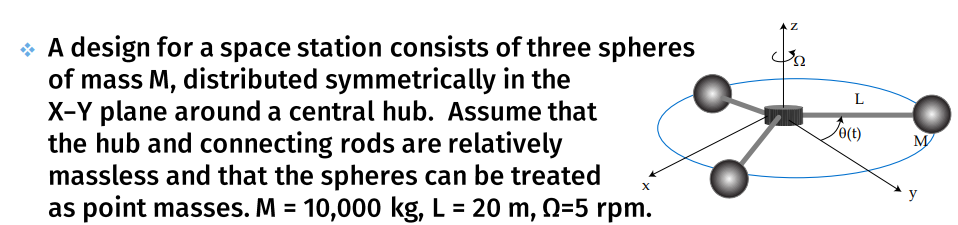

### Problem 7.1 What is the Inertia about the Z-Axis?

We will use the point mass formulation for MoI

#### 
$$I_z = \sum m_i (x_i^2 + y_i^2)$$


WLOG, we can assume M1 is at $\theta = 0$, M2 is at $\theta = \frac{2\pi}{3}$, and M3 is at $\theta = \frac{4 \pi}{3}$. Through trigonometry, $x_i^2 + y_i^2 = L^2$, due to the pythagorean identity with sines and cosines.

M       = 100000;       % kg
L       = 20;           % m
Omega   = 5 * pi/30;    % rad/s
Iz      = 3 * M* L^2;   % kg-m^2
fprintf("The MoI about Z is %f kg-m^2", Iz);

The MoI about Z is 120000000.000000 kg-m^2

### Problem 7.2 Show that the Inertia about X and Y axes are $1.5 M L^2$, irrespective of $\theta$

Since this is in the $X-Y$ plane, we know $z_i = 0$. Thus, for $I_x$, we have the formula

#### 
$$I_x = \sum_{i} m_i y_i^2$$


and for $I_y$, we have 

#### 
$$I_y = \sum_i m_i x_i^2$$


Now, assume we perturb our initial angles by $\theta'$. That means $y_1 = sin\left(\frac{2\pi}{3} + \theta'\right)$, $y_2 = sin \left( \frac{4 \pi}{3} + \theta' \right)$, $y_3 = sin\left(2 \pi + \theta' \right)$

#### 
$$I_x = \sum_i m_i y_i^2 = ML^2 \left( sin \left( \frac{2\pi}{3} + \theta' \right)^2 + sin \left( \frac{4 \pi}{3} + \theta' \right)^2 + sin \left( 2\pi + \theta' \right)^2 \right)$$


#### 
$$sin \left( \frac{2 \pi}{3} + \theta' \right)^2 = \left( sin\left(\frac{2 \pi}{3} \right) cos(\theta') + cos\left(\frac{2\pi}{3}\right)sin(\theta')\right)^2 = \left( \frac{\sqrt{3}}{2} cos(\theta') - \frac{1}{2} sin(\theta') \right)^2 = \frac{3}{4} cos^2(\theta') + \frac{1}{4} sin^2(\theta') - \frac{\sqrt{3}}{4} sin(\theta') cos(\theta')$$


Following the same logic with sine addition formulas, we also get

#### 
$$sin\left(\frac{4 \pi}{3} + \theta' \right)^2 = \frac{3}{4} cos^2\left(\theta'\right) + \frac{1}{4} sin^2 \left(\theta'\right) + \frac{\sqrt{3}}{4} sin(\theta') cos(\theta')$$


#### 
$$sin(2 \pi + \theta')^2 = sin^2(\theta')$$


Adding together, we get

#### 
$$I_x = \sum_i m_i y_i^2 = ML^2 \left( 2 \times \frac{3}{4} cos^2(\theta') + 2 \times \frac{1}{4} sin^2(\theta') + sin^2(\theta')\right) = \frac{3}{2} ML^2 \left( cos^2(\theta') + sin^2(\theta') \right) = \frac{3}{2}ML^2$$


Similarly, we will do the same for $I_y$,

#### 
$$I_y = \sum_i m_i x_i^2 = ML^2 \left( cos\left(\frac{2\pi}{3} + \theta' \right)^2 + cos \left( \frac{4 \pi}{3} + \theta' \right)^2 + cos ( 2 \pi + \theta') ^2 \right)$$


#### 
$$I_y = ML^2 \left( cos^2 (\theta') + \frac{1}{2} cos^2(\theta') + \frac{3}{2} sin^2(\theta') \right) = \frac{3}{2} ML^2$$


### Problem 7.3 Show that the spin about the Z-axis is stable

Ix = 1.5 * M * L^2;
Iy = 1.5 * M * L^2;
fprintf("X and Y Axis MOI: %f kg-m^2", Ix);

X and Y Axis MOI: 60000000.000000 kg-m^2

if (Iz > Ix && Iz > Iy)
    fprintf("Iz > Ix and Iz > Iy, thus spin is stable about Z");
else
    fprintf("Iz < Ix OR Iz < Iy, so spin is not stable about Z");
end

Iz > Ix and Iz > Iy, thus spin is stable about Z

### Problem 7.4 Find the Nutation Period

The nutation frequency is defined as

#### 
$$\lambda = \Omega \left( \frac{I_z - I_x}{I_x} \right)$$


so the Nutation period would be

#### 
$$T = \frac{1}{\lambda} = \frac{I_x}{\Omega \left(I_z - I_x \right)}$$


nutationFreq   = Omega * (Iz - Ix) / Ix; % 1/s
nutationPeriod = 1 / nutationFreq;       %s
fprintf("The nutation period is %f (sec)", nutationPeriod);

The nutation period is 1.909859 (sec)

## Problem 8

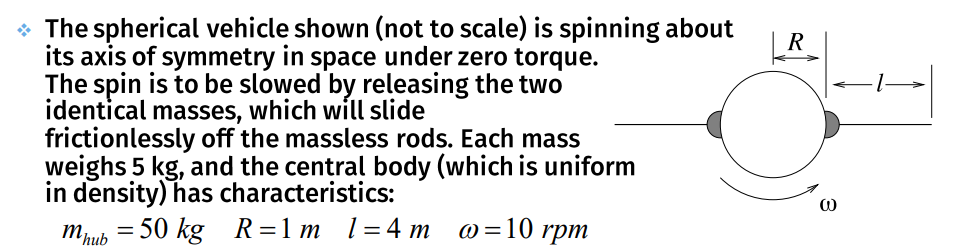

### Problem 8.1 Calculate the Inertia of the central body

From the notes, the inertia for the sphere rotating about its axis of symmetry is $I = \frac{2}{5} MR^2$.

mHub  = 50;         % kg
rHub  = 1;          % m
l_rod = 4;          % m
omega = 10 * pi/30; % rad/s

Ihub = 2 * mHub * rHub^2 / 5;
fprintf("The inertia of the hub is %f kg-m^2", Ihub);

The inertia of the hub is 20.000000 kg-m^2

### Problem 8.2 Calculate the spacecraft inertia at the time shown in the picture

Each point mass $m$ is a distance $r%$ away, and rotating about the same axis. We will sum the individual inertias to get the total spacecraft inertia

Mpm = 5;               % kg
r   = rHub;            % m
Ipm = Mpm * r^2;       % kg-m^2
Isc = Ihub + 2 * Ipm;  % kg-m^2
fprintf("The inertia of the spacecraft is %f (kg-m^2)", Isc);

The inertia of the spacecraft is 30.000000 (kg-m^2)

### Problem 8.3 What is the spin rate when the masses reach the tip?

As the masses reach the tip, the MOI is increased so the spin rate is decreased, due to conservation of angular momentum. 

First we must find the inertia when the point masses are at the edge of the spacecraft

r = rHub + l_rod;               % m
Ipm_end = Mpm * r^2;            % kg-m^2
Isc_end = Ihub + 2 * Ipm_end;   % kg-m^2
fprintf("The inertia of the s/c with the point masses at the end is %f (kg-m^2)", Isc_end);

The inertia of the s/c with the point masses at the end is 270.000000 (kg-m^2)

Now, by conservation of angular momentum we have

#### 
$$I_{sc,end} \omega_{f} = I_{sc} \omega_0$$


omega_f = Isc * omega / Isc_end; % rad/s
fprintf("The angular rate of the s/c once the masses are extended is %f (rad/s) ", omega_f);

The angular rate of the s/c once the masses are extended is 0.116355 (rad/s) 

### Problem 8.4 At the edge, the masses fly off the wire. What is their speed at this time?

Linear speed is calculated as 


$$v = r \omega$$


v = r * omega_f;
fprintf("The speed of the masses once they fly off is %f (m/s)", v);

The speed of the masses once they fly off is 0.581776 (m/s)

## Problem 9

## Problem 10

### Problem 10.1 A plant has 3 roots at -2, -3, and -5. It has no zeros. Write the transfer function.

plantTF = zpk([], [-2, -3, -5],1)

plantTF =
 
          1
  -----------------
  (s+2) (s+3) (s+5)
 
Continuous-time zero/pole/gain model.



### Problem 10.2 Is the system stable?

Yes, the system is stable. The denominator has no change in signs, and all roots are in the LH side of the complex plane. 

### Problem 10.3 Consider the general 3rd order system

#### 
$$\frac{1}{s^3 + as^2 + bs +c}$$


using Routh-Hurwitz Criterion, show that the system is stable iff 

#### 
$$a > 0, \ c > 0, \ b > \frac{c}{a}$$


From the RH Criterion, we know that all signs need to stay the same. Since the sign on $s^3$ is positive ($a_3 = 1$), we need $c > 0$. Calculating $a_2 - \frac{a_3 a_0}{a_1}$ from the notes, we get

#### 
$$a - \frac{1 \times c}{b} > 0 \Rightarrow a - \frac{c}{b} > 0 \Rightarrow b > \frac{c}{a}$$


our last condition for $b$ to be positive is for $a > 0$. Thus, we have shown all the conditions for stability, given that $a_3 = 1$.

### Problem 10.4 Close the loop with $C(s) = 1000$. What is the CLTF? 

#### 
$$G_{CL}= \frac{CP}{1 + CP}$$


where 

#### $C = 1000$, $P = \frac{1}{(s+2)(s+3)(s+5)}$

Putting this together, our CLTF is 

#### 
$$G_{CL} = \frac{1000}{(s+2)(s+3)(s+5) + 1000}$$


### Problem 10.5 What is the characteristic equation for the CLTF?

The characteristic equation is the denominator of $G_{CL}$

#### 
$$(s+2)(s+3)(s+5) + 1000$$


#### 
$$s^3 + 10s^2 + 31s + 30 + 1000 = s^3 + 10s^2 + 31s + 1030$$


### Problem 10.6 Using the RH Criterion, show that $C(s) = 1000$ destabilizes the system

From 10.3, we know that $b > \frac{c}{a}$, with $a = 10, \ b = 31, \ c = 1030$. Since $b \not > \frac{1030}{10}$, the system fails the RH Criterion and is not stable.

## Problem 11

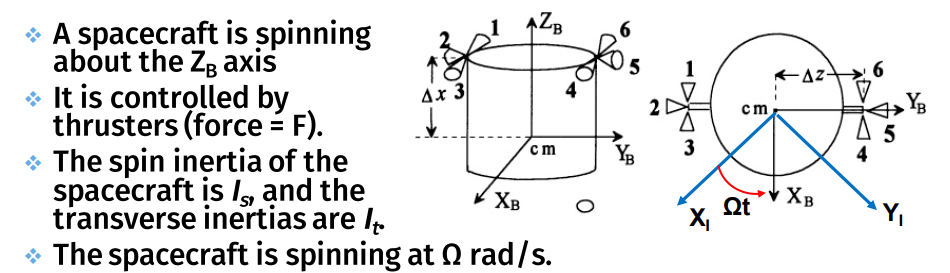

### Problem 11.1 What is the torque when Thrusters 1 and 6 are fired?

#### $F_1 = (F_x, 0, 0)$, $F_6 = (F_x, 0, 0)$

#### $r_{cm,1} = (0, - \Delta z, \Delta x)$, $r_{cm,6} = (0, \Delta z, \Delta x)$

#### 
$$T_1 = r_{cm,1} \times F_1 = (0, F_x \Delta x, F_x \Delta z)$$


#### 
$$T_6 = r_{cm,6} \times F_6 = (0, F_x \Delta x, - F_x \Delta z)$$


#### 
$$T_1 + T_6 = (0, 2 F_x \Delta x, 0)$$


### Problem 11.2 Write the DCM at time t, with $\Omega t$ being the angle from the inertial to body frame.

Since it is only rotating about z, our DCM is just a z rotation

#### 
$$A_{\Omega t} = \pmatrix{ cos(\Omega t) & sin( \Omega t) & 0 \cr - sin(\Omega t) & cos( \Omega t) & 0 \cr 0 & 0 & 1}$$


### Problem 11.3 Write the linearized Equations of Motion for when the Thrusters are fired

Using the vector equation

#### 
$$T_{ext} = I \dot{\omega} + \omega^{ \times} I \omega$$


#### 
$$\pmatrix{T_x \cr T_y \cr T_z} = \pmatrix{I_t & 0 & 0 \cr 0 & I_t & 0 \cr 0 & 0 & I_s} \pmatrix{\dot{\omega}_x \cr \dot{\omega}_y \cr \dot{\omega}_z} + \pmatrix{0 & -\omega_z & \omega_y \cr \omega_z & 0 & -\omega_x \cr -\omega_y & \omega_x & 0} \pmatrix{I_t \omega_x \cr I_t \omega_y \cr I_s \omega_z}$$


#### 
$$\pmatrix{0 \cr 2 F \Delta x \cr 0}  = \pmatrix{I_t \dot{\omega}_x - I_t \omega_z \omega_y + I_s \omega_y \omega_z \cr I_t \dot{\omega}_y + I_t \omega_z \omega_x - I_s \omega_x \omega_z \cr I_s \dot{\omega}_z}$$


Now, we will linearize by setting $\omega_z \rightarrow \omega_z + \Omega$, and all products of angular velocities go to zero.

#### 
$$\pmatrix{0 \cr 2 F \Delta x \cr 0}  = \pmatrix{I_t \dot{\omega}_x - I_t (\omega_z + \Omega) \omega_y + I_s \omega_y( \omega_z  + \Omega) \cr I_t \dot{\omega}_y + I_t (\omega_z + \Omega) \omega_x - I_s \omega_x (\omega_z + \Omega) \cr I_s \dot{\omega}_z}$$


#### 
$$\pmatrix{0 \cr 2 F \Delta x \cr 0}  = \pmatrix{I_t \dot{\omega}_x - I_t  \Omega \omega_y + I_s \omega_y \Omega \cr I_t \dot{\omega}_y + I_t  \Omega \omega_x - I_s \omega_x  \Omega \cr I_s \dot{\omega}_z}$$



$$\pmatrix{0 \cr \frac{1}{I_t} 2 F \Delta x \cr 0}  = \pmatrix{ \dot{\omega}_x + \left( \frac{I_s - I_t}{I_t} \Omega \right) \omega_y \cr  \dot{\omega}_y - \left( \frac{I_s - I_t}{I_t} \Omega \right) \omega_x \cr I_s \dot{\omega}_z}$$
